# ODE Equation

## **First-order ODE:**

 y' = 2x + 1, y(0) = 0

**Exact solution:**

y(x) = x (x + 1)

% Define the ODE and its initial condition
f = @(x, y) 2 * x + 1;
y0 = 0;

% Define the exact solution
y_exact = @(x) x.*(x+1);

% Define the time interval and step size
t_start = 0;
t_end = 100000;
h = 0.1;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(size(tspan));
y_forward(1) = y0;
for i = 2:length(tspan)
    y_forward(i) = y_forward(i-1) + h * f(tspan(i-1), y_forward(i-1));
end
time_forward = toc * 1000;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(size(tspan));
y_backward(1) = y0;
for i = 2:length(tspan)
    y_backward(i) = y_backward(i-1) + h * f(tspan(i),y_backward(i));
end
time_backward = toc * 1000;

y_forward

y_forward = 1.0e+10 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


y_backward

y_backward = 1.0e+10 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward);
error_backward = abs(y_exact(tspan) - y_backward);

% Error per
per_error_arr_fe = error_forward ./ y_exact(tspan) * 100

per_error_arr_fe =        NaN    9.0909    8.3333    7.6923    7.1429    6.6667    6.2500    5.8824    5.5556    5.2632    5.0000    4.7619    4.5455    4.3478    4.1667    4.0000    3.8462    3.7037    3.5714    3.4483    3.3333    3.2258    3.1250    3.0303    2.9412    2.8571    2.7778    2.7027    2.6316    2.5641    2.5000    2.4390    2.3810    2.3256    2.2727    2.2222    2.1739    2.1277    2.0833    2.0408    2.0000    1.9608    1.9231    1.8868    1.8519    1.8182    1.7857    1.7544    1.7241    1.6949


per_error_arr_be = error_backward ./ y_exact(tspan) * 100

per_error_arr_be =        NaN    9.0909    8.3333    7.6923    7.1429    6.6667    6.2500    5.8824    5.5556    5.2632    5.0000    4.7619    4.5455    4.3478    4.1667    4.0000    3.8462    3.7037    3.5714    3.4483    3.3333    3.2258    3.1250    3.0303    2.9412    2.8571    2.7778    2.7027    2.6316    2.5641    2.5000    2.4390    2.3810    2.3256    2.2727    2.2222    2.1739    2.1277    2.0833    2.0408    2.0000    1.9608    1.9231    1.8868    1.8519    1.8182    1.7857    1.7544    1.7241    1.6949



% Mean Error Per
mean_error_fe = mean(per_error_arr_fe(2:end))

mean_error_fe = 0.0011

mean_error_be = mean(per_error_arr_be(2:end))

mean_error_be = 0.0011

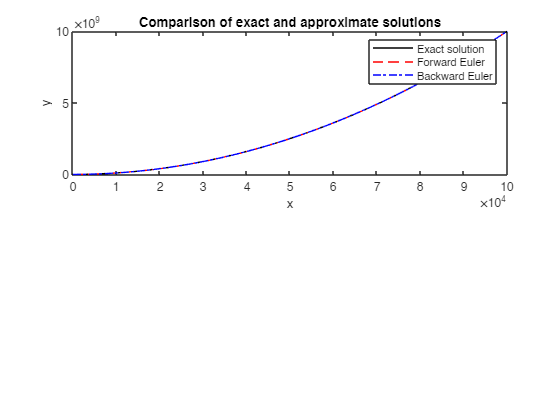


% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward, 'r--', tspan, y_backward, 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 47.105500 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 49.779200 seconds


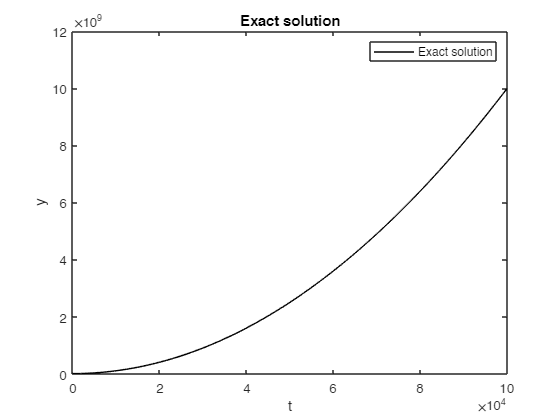

figure;
plot(tspan, y_exact(tspan), 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');